# **Implementación EC en matlab de modulación digital y analógica**

Andrés Fernando Jerez Medina - 2190416

Jorge Eduardo Angarita Perez - 2190427

Sergio Sebastián Oliveros Sepulveda - 2190396 

## **Punto 2:**

Como se observa la frecuencia de muestreo es 5 veces mayor a la frecuencia del mensaje, evitando aspi efectos de aliasing y permitiendo ver una mayor parte de la señal en el espectro.

Parámetros:

fm = 100;   %Frecuencia del mensaje
fc = fm*10; %Frecuencia de la portadora
fs = fc*5;  %Frecuencia de muestreo
Ts = 1/fs;  %Periodo de muestreo
nper = 2;   %Periodos de la señal
Tend = 1/fm*nper; %Tiempo de simulación
Ac = 1;     %Amplitud de la portadora
Df = 100;   %Desviación de frecuencia

Modulación en tiempo:

t = 0:Ts:(Tend-Ts);
n = length(t);

m_t = 10*sin(2*pi*fm*t); %Construcción de la señal mensaje 

Ahora, a partir de nuestro mensaje construimos las funciones x(t) y y(t) de la siguiente manera:

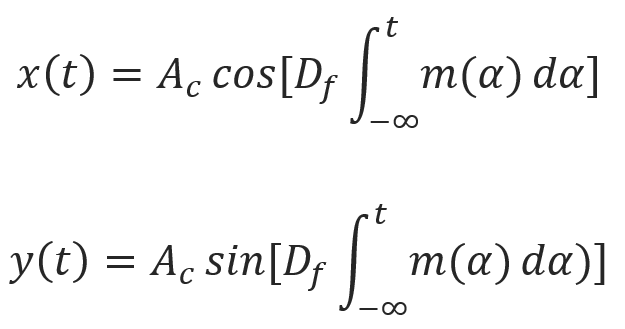

Para esto se definió previamente un Df de 100 y debido a que es modulación en frecuencia la amplitud de portadora se estableció como 1. La componente de frecuencia de las funciones corresponde a la multipicación de Df con la integral del mensaje, al estar en el dominio discreto esta integral fue definida como una sumatoria de cada uno de valores multiplicado por el tiempo de muestreo. A continuación se muestra cómo se definieron las señales:   

x_t = Ac*cos(Df*cumsum(m_t)*Ts); %Parte real de g(t)
y_t = Ac*sin(Df*cumsum(m_t)*Ts); %Parte imaginaria de g(t)

g_t = x_t + 1j*y_t; %Envolvente compleja

s_t = x_t.*cos(2*pi*fc*t)-y_t.*sin(2*pi*fc*t); %Señal modulada

Las señales obtenidas fueron graficadas en el tiempo multiplicando el número de muestras de cada una de ellas por el periodo de muestreo. Los resultados se muestran a continuación:

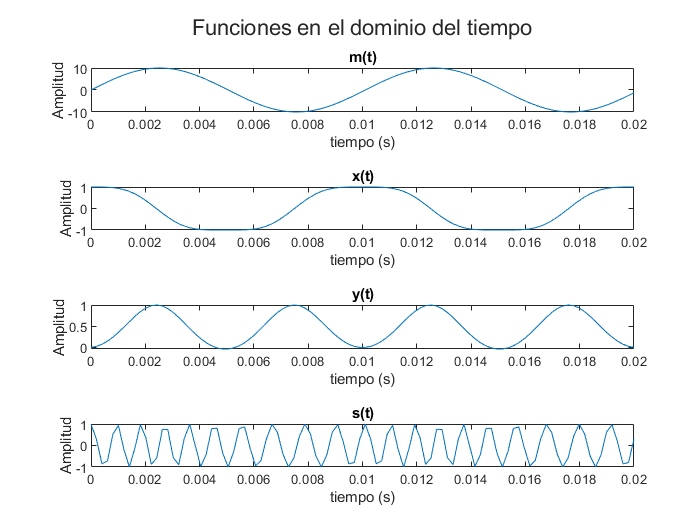

p = tiledlayout(4,1);
title(p,"Funciones en el dominio del tiempo")
t = linspace(0,length(m_t),length(m_t))*Ts;

nexttile; plot(t,m_t); title("m(t)"); ylabel("Amplitud"); xlabel("tiempo (s)")
nexttile; plot(t,x_t); title("x(t)"); ylabel("Amplitud"); xlabel("tiempo (s)")
nexttile; plot(t,y_t); title("y(t)"); ylabel("Amplitud"); xlabel("tiempo (s)")
nexttile; plot(t,s_t); title("s(t)"); ylabel("Amplitud"); xlabel("tiempo (s)")

En frecuencia:

Para observar el espectro de las señales en el dominio de la frecuencia se realizó la tranformada de Fourier de cada función:

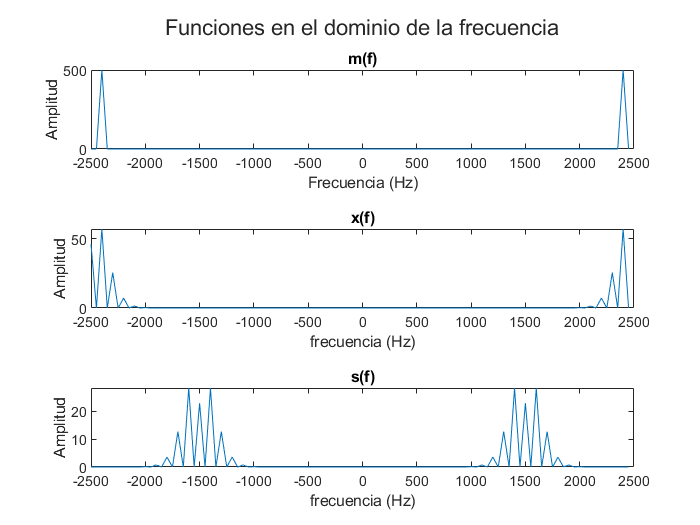

m_f = fft(m_t);
g_f = fft(g_t);
s_f = fft(s_t);

f = (-n/2:n/2 - 1)*(fs/n);
figure
t = tiledlayout(3,1);
title(t,"Funciones en el dominio de la frecuencia")

nexttile; plot(f,abs(m_f)); title("m(f)"); ylabel("Amplitud"); xlabel("Frecuencia (Hz)")
nexttile; plot(f,abs(g_f)); title("x(f)"); ylabel("Amplitud"); xlabel("frecuencia (Hz)")
nexttile; plot(f,abs(s_f)); title("s(f)"); ylabel("Amplitud"); xlabel("frecuencia (Hz)")

Y por último, se muestra la potencia de cada una de las señales vistas anteriormente:

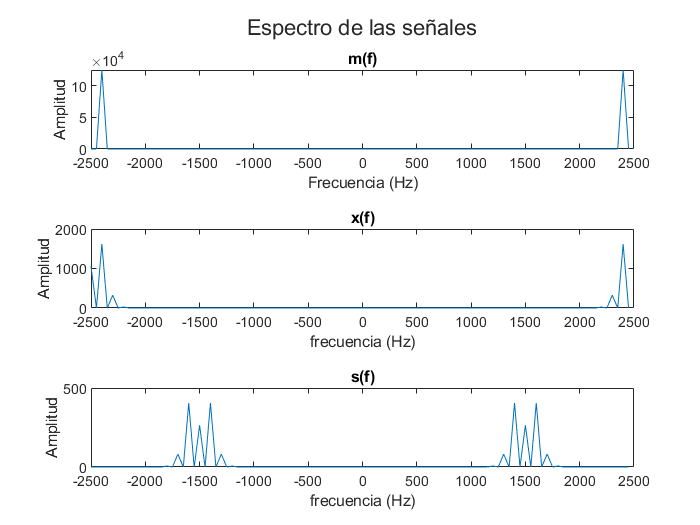

figure
t = tiledlayout(3,1);
title(t,"Espectro de las señales")
nexttile; plot(f,(abs(m_f).^2)/2); title("m(f)"); ylabel("Amplitud"); xlabel("Frecuencia (Hz)")
nexttile; plot(f,(abs(g_f).^2)/2); title("x(f)"); ylabel("Amplitud"); xlabel("frecuencia (Hz)")
nexttile; plot(f,(abs(s_f).^2)/2); title("s(f)"); ylabel("Amplitud"); xlabel("frecuencia (Hz)")